# **변경사항**

# **주의**

시작 전에, 이 파일이 들어 있는 폴더를 matlab 경로에 추가해 주세요.

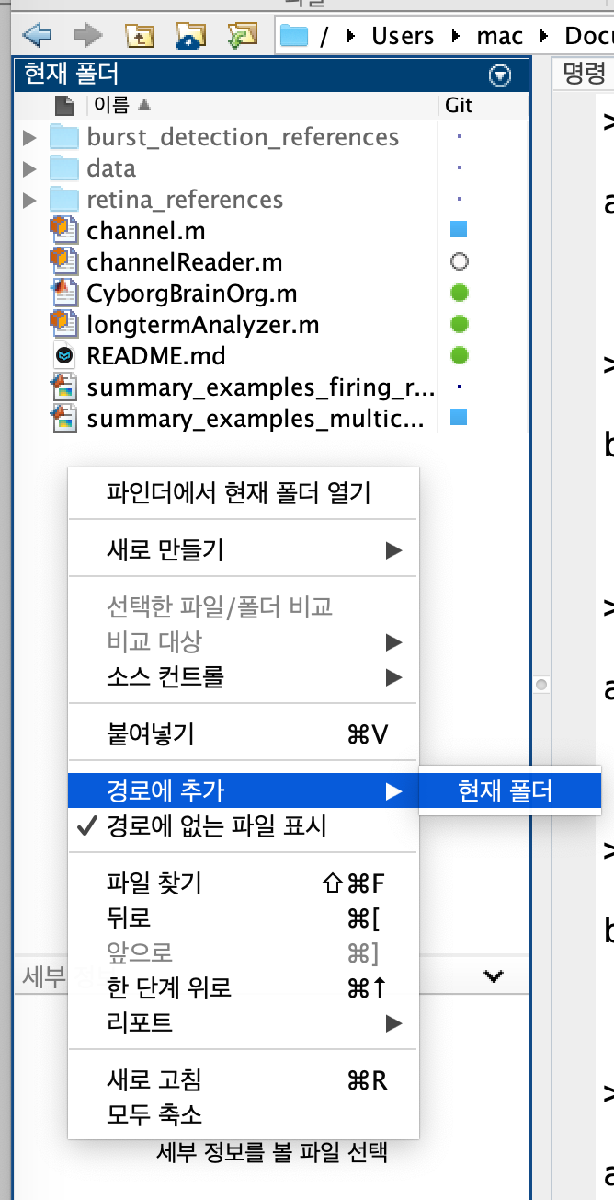

# **관련 파일 목록**

# **요약**

## 1

# **본문: **

## 0. 데이터 불러오기 및 전처리

### 0.1. 데이터 불러오기

channel object 생성 및 데이터 처리: reading_method_guide.mlx 참고

reader = channelReader();
tic 
%                                 filename,        channelColumnIdx, timeColumnIdx, startRowIdx, startColIdx, sampleRate
reader.readMultiChannelFile("./data/1_singleunit wave.xlsx", 1,        3,             7,             4,           nan); %일단 파일을 불러옴

This file has 16 channels: 

ans =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16



toc % 코드 실행 시간 측정. 오래 걸림.

Elapsed time is 76.897122 seconds.



%                 organoid, channel, month 
o1_ch8_m1 = reader.readSingleChannelFromFile(1, 8, 1); %8번 채널 데이터를 불러옴 

channel number = 8
sampling rate = 24414.062743Hz
starts at 0.000000, ends at 23.152517, duration = 23.152517
number of timestamps = 565248



### **(misc) Bandpass filter preview graph & figure data export basics(line graph)**

channel object에서 raw 데이터를 불러와서 bandpass filter 적용시 어떤 결과가 나오는지 그래프로 확인하고, 역으로 그래프에서 데이터를 뽑아내는 방법도 설명

#### **Bandpass filter preview graph**

%apply bandpass filter 300-3000hz
figure
bandpass(o1_ch8_m1.raw, [300,3000], o1_ch8_m1.sf)
sgtitle("bandpass filter preview")

#### **Figure data export basics(line graph)**

Matlab의 figure의 구조는 아래와 같습니다. 

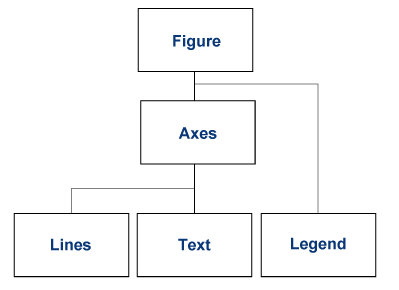

axes하나가 그래프 하나를 의미합니다. **0.3.1**의 figure의 경우, figure 하나에 그래프가 2개 있습니다. 그래서 axes가 2개 있습니다.(3번째, 5번째 원소)

h = gcf; %가장 최근에 그린 figure를 집어옴
axesObjs = get(h, 'Children') %figure의 하위 object들을 가져옴

5번째 원소인 axes를 가져오겠습니다. axes 아래에는 그래프를 구성하는 chart objects들(Line, Bar, Scatter 등)이 있습니다. 이 axes의 경우 line이 두 개 있습니다. 선이 두 개 그어져 있기 때문입니다. 

dataObjs = get(axesObjs(5), 'Children') %'대역통과 필터링'에 해당하는 axes의 하위 object를 가져옴

2번째 원소인 (원래 신호)를 가져오겠습니다. 이 line 안에 데이터가 들어있습니다. XData, YData가 바로 그것입니다. 3차원 그래프가 아니므로 ZData는 없습니다.

lineObj = dataObjs(2)

엑셀 파일로 뽑기 위해 table 오브젝트를 만듭니다. array도 엑셀로 뽑을 수 있지만, table이 열 이름을 지정하기가 더 편합니다. column array를 input으로 넣으면 자동으로 array 이름을 열 이름으로 정합니다.

lineX = (lineObj.XData)';
lineY = (lineObj.YData)';
lineData = table(lineX, lineY)
writetable(lineData, "lineData.xlsx") %파일명을 .xlsx로 하여 엑셀 파일로 저장

### **0.1 Bandpass filter 적용**

**(method) **`bandPass`

**파라미터 1개 **

- `passBand` : [숫자, 숫자] 포맷으로, hz 단위로 입력

 bandpass filter 실제로 적용하여 channel object 내에 저장

%                   passband
o1_ch8_m1.bandPass([300,3000]); %apply bandpass filter 300-3000hz

### **0.2. Spike detection 수행**

**(method) **`detectSpikes`

**paramter 3개**

- `thres`: spike 분류 기준. 5를 입력하면 평균+5표준편차 밖의 값을 spike로 분류 ((reference code에서는 5)

- `preTime`: spike waveform의 spike 앞쪽 너비. milisecond 단위 (reference code에서는 2)

- `postTime`: spike waveform의 spike 뒷쪽 너비. milisecond 단위 (reference code에서는 2)

주의: 코드 내 threshold에 minus가 붙어 있습니다, 즉 이 알고리즘은 local minimum을 찾는 알고리즘입니다 (레퍼런스 코드에서 이렇게 구현되어 있었습니다)

                        %thres, preTime, postTime
o1_ch8_m1.detectSpikes(5,2,2);

number of spikes found : 113


### **0.2. ISI 계산**

**(method) **`getISIvaluesBeforePCA`

PCA 및 k-means를 통해 spike들을 cluster별로 나누기 전에, 발견한 모든 spikes를 대상으로 ISI 계산**(milisecond 단위)**하고 data 가져오는 method:

**paramter 없음**

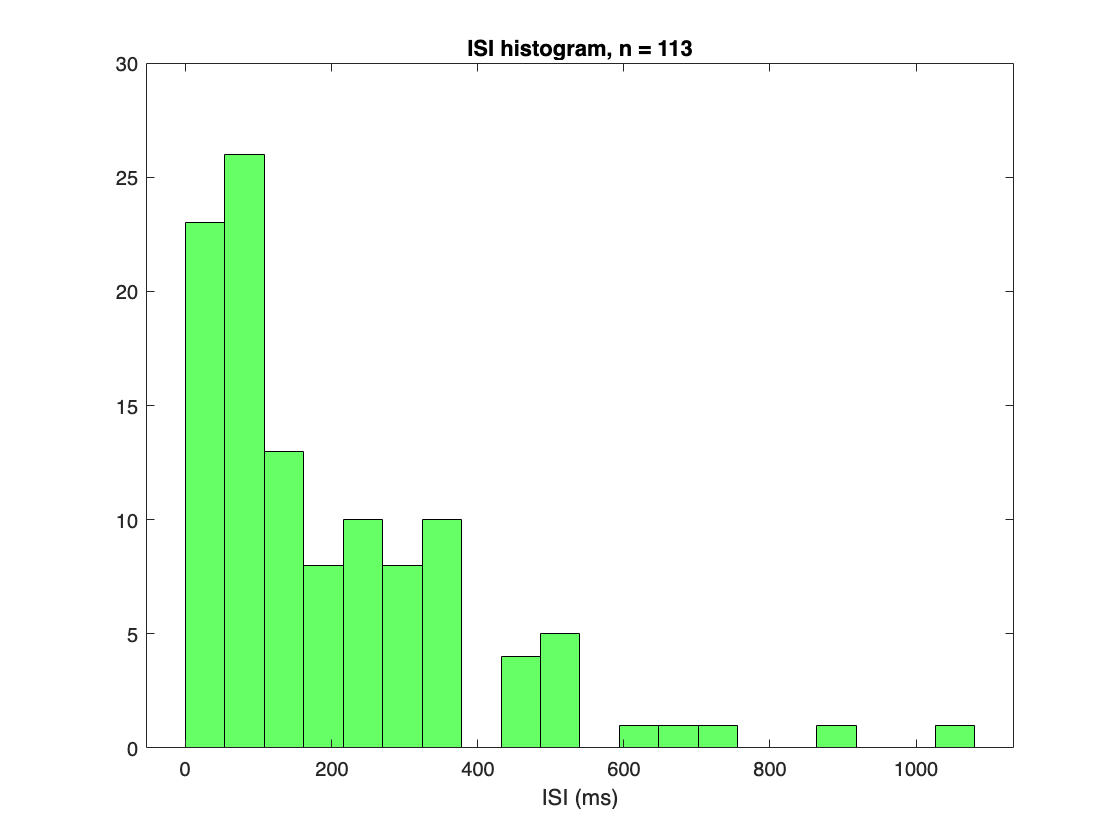

ISIvaluesBeforePCA = o1_ch8_m1.getISIvaluesBeforePCA(); %PCA, kmeans 전에 전체 spike 대상 ISI 계산값 가져오기
nSpikes = o1_ch8_m1.nSpikes;

figure
h1 = histogram(ISIvaluesBeforePCA, 20); % bin 개수 20개로 설정. 변경 가능
title('ISI histogram, n = ' + string(nSpikes) ); %plot 제목 
xlabel('ISI (ms)'); % plot x축 변수 이름
h1.FaceColor = "green"; %색상 지정

#### **0.2.1. histogram figure export**

h = gcf; %가장 최근에 그린 figure를 집어옴
axesObjs = get(h, 'Children') %figure의 하위 object들을 가져옴. 이 figure의 경우 단 하나의 axes만 존재
dataObjs = get(axesObjs(1), 'Children') %axes 아래에 histogram이라는 object 하나밖에 없음

histogram object 안에 있는 데이터에 접근:

histogramOriginalData = (dataObjs.Data)' %원본 데이터
histogramBinEdges = (dataObjs.BinEdges)' %히스토그램 각 bar의 아래 꼭지점. 마지막 점을 지워서 왼쪽 값들만 사용하거나, 첫 점을 지워서 오른쪽 값들만 사용
histogramBinEdges(end) = []; % 마지막 점을 지움
histogramValues = (dataObjs.Values)' %히스토그램 각 bar의 높이(count)
writetable(table(histogramBinEdges, histogramValues), "histoData.xlsx") %파일명을 .xlsx로 하여 엑셀 파일로 저장

### **0.3. MaxInterval method를 이용한 non-network burst detection**

#### **(method) detectBurstsMI**

- 김은지 선생님이 보내주신  reference paper [1]에서 사용한 burst detection method 중 `MaxInterval method `사용

- 5개의 parameter를 이용해 burst를 판별

- 아래 표의 상단 방법에 해당

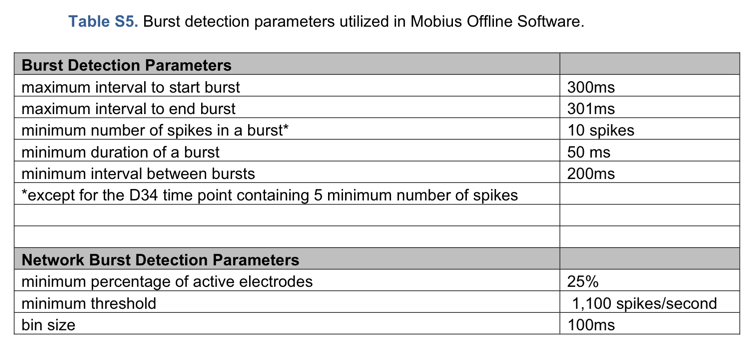

**(코드 구현을 위한) burst의 정의: **특정 조건을 만족하는 spike timestamp의 집합

- 같은 burst 내의 spike는 서로 충분히 가까움

- 다른 burst와는 충분히 멀리 떨어져 있음

- burst 내부에 충분히 많은 spike가 있음

- spike가 충분히 길게 이어져 있음

**paramter 5개**

- `begISI ``: ISI 값이 이 값보다 작으면 burst가 시작된 것으로 인정`

- `endISI ``: ISI 값이 이 값보다 크면 burst가 끝난 것으로 인정`

- `minSpikes ``: burst에 포함된 spike의 개수가 이 값을 넘어야 burst로 인정`

- `minDurn``: burst를 구성하는 첫 spike부터 마지막 spike까지의 time interval이 이 값보다 커야 burst로 인정(milisecond 단위)`

- `minIBI``: 두 burst 간의 간격(앞 burst의 마지막 spike와 뒤 burst의 첫 spike 사이의 time inverval)이 이 값보다 커야 burst로 인정`

   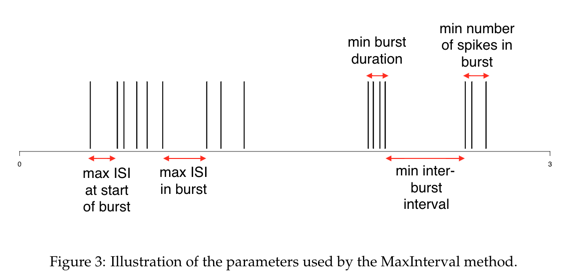

[2]

**코드 구현 특이사항**

- matlab reference code는 존재하지 않음 -> `Stephen Eglen이 2007년에 R로 구현한 코드(IGM.MEA 패키지)를 matlab에 맞게 직접 수정`

- `3단계로 나누어 구현`

- finding :` begISI, endISI를 이용하여 burst 후보를 선정`

- merging `: 1에서 구한 후보들 중 둘 간의 간격이 minIBI보다 작은 경우 하나의 `burst로 간주하여` 합침`

- deleting `: 2에서 얻은 후보들 중 minDurn과 minSpikes를 충족하지 못하는 것들을 제거하여 최종적으로 `burst를` 선별`

% begISI, endISI , minSpikes, minDurn, minIBI, (in milisecond)
% the order of the parameters is the same as the reference [1]
burstDetectionResult = o1_ch8_m1.detectBurstsMI(300, 301, 10, 50, 200) %[1]과 똑같은 parameter 값을 사용

phase 1 result: found 22 bursts, using parameters begISI and endISI

phase 2 result: after merging by minIBI, 22 bursts left

phase 3 result: 20 bursts were removed whose duration is less than 50 milisecond or have spikes less than 10 

burstDetectionResult = 2×6 table
    beg    end     IBI     nSpikes     durn     meanISI
    ___    ___    _____    _______    ______    _______

     9      22      NaN      14       1855.9    142.76 
    85     102    15529      18       1331.7    78.335 


R 원본 코드로 실행한 것과 같은 결과가 나옴을 확인하였음(원본 R 코드와 테스트 코드는 같은 폴더에 첨부).

**결과 해석**

- 결과물: 위와 같은 내용의 table

- 각 행이 하나의 burst를 의미

- 각 열의 의미:

- `beg` : burst 시작점 spike의 번호. 1행에서 `beg = 9`라는 것은 첫 번째 burst의 첫 spike가 전체 spike 중 9번째 spike라는 의미(즉 `o1_ch8_m1.spikeTimestamps(9)` 혹은 `o1_ch8_m1.spikeWaveforms(9, :)`로 접근 가능한 spike)

- `end` : burst 끝점 spike의 번호. 1행에서 `end = 22`라는 것은 첫 번째 burst의 마지막 spike가 전체 spike 중 22번째 spike라는 의미(즉 `o1_ch8_m1.spikeTimestamps(22) `혹은 `o1_ch8_m1.spikeWaveforms(22, :)`로 접근 가능한 spike)

- `IBI` : 해당 burst와 다음 burst 사이의 간격

- nSpikes : 해당 burst 내 spike 개수

- `durn` : 해당 burst의 길이. 첫 spike의 timestamp와 마지막 spike의 timsestamp의 차.

- `meanISI` : 해당 burst 내의 spike끼리 ISI를 계산하여 평균한 것

[1] Fair, S. R., Julian, D., Hartlaub, A. M., Pusuluri, S. T., Malik, G., Summerfied, T. L., Zhao, G., Hester, A. B., Ackerman, W. E., Hollingsworth, E. W., Ali, M., McElroy, C. A., Buhimschi, I. A., Imitola, J., Maitre, N. L., Bedrosian, T. A., & Hester, M. E. (2020). Electrophysiological Maturation of Cerebral Organoids Correlates with Dynamic Morphological and Cellular Development. *Stem Cell Reports*, *15*(4). https://doi.org/10.1016/j.stemcr.2020.08.017

[2] Cotterill, E., & Eglen, S. J. (2019). Burst Detection Methods. In *Advances in Neurobiology* (Vol. 22). [https://doi.org/10.1007/978-3-030-11135-9_8](https://doi.org/10.1007/978-3-030-11135-9_8)

### **0.4. PCA 수행**

**(method) **`getPCScores`

주의

- PCA는 각 축의 분산을 최대한 보존하는 principal component를 찾는 알고리즘이므로, 특정 waveform의 scale이 지나치게 크다면 분산에 많이 기여하게 되어 그 waveform을 principal component로 잘못 인식할 수 있음. 일반적으로 PCA를 비롯한 차원축소 알고리즘들이 비슷한 문제를 가지고 있기 때문에, 알고리즘 수행 전에 각 데이터포인트의 scale을 통일하는 scaling을 필수적으로 수행함

- Scaling 방법은평균을 빼고 표준편차로 나누는 standard scaling, min을 빼고 (max-min)으로 나누는 0-1 scaling 등이 있음

- 물론 데이터가 scale이 원래 일정하다면 굳이 standardization을 수행할 필요가 없음. Reference code에서는 standard scaling 코드를 써 놓고 주석 처리해 놓았음. 이 코드에서는 주석 처리를 해제하고 standard scaling을 수행하도록 하였음

- PCA 수행 후 explained variance plot을 꼭 확인해야 함. 첫 두 PC가 설명하는 분산의 양이 충분히 커야(보통 70% 이상) 2차원만 남기고 나머지 차원을 버리는 것이 정당화됨

- **경고 메시지 "X의 열은 기계 정밀도 내에서 1차 종속입니다"는 spike waveform의 시작과 끝 부분이 평탄해서 비슷한 값을 가지기 때문에 발생. 어차피 PCA를 통해서 차원축소를 할 것이기 때문에 문제되지 않음**

o1_ch8_m1.getPCScores();

### **0.5. K-means clustering 수행**

**(method) **`getKmeansClusters`

**parameter 2개**

- `clusternum`: cluster 개수(reference code에선 3)

- `seednum`: 알고리즘의 초기값에 영향을 미치는 random number seed(reference code에 없음)

주의

- k-means clustering은 해를 해석적으로 구하지 못하고 EM algorithm이라는 iterative algorithm을 사용하는데, 초기값에 큰 영향을 받음. 초기값이란 각 점의 맨 처음 cluster 배정을 의미하며, 랜덤으로 할당함. 일반적으로 이러한 EM algorithm 기반 clustering을 수행할 때는 여러 seed number를 사용하여 알고리즘을 여러 번 돌려봄.

- k-means clustering에서 cluster 개수(clusternum)는 자동으로 최적값이 정해지지 않으며, 정답이 없는 비지도학습이기에 최적값을 알 수도 없음. 일반적으로 사용자가 여러 clusternum을 시도해 보며 적절한 값을 찾아야 함.

- 결론적으로, 여러 clusternum과 seednum의 조합을 시도하면서 plot을 보고 사용자 눈에 적절한 결과가 나올때까지 진행해야 함.

                           %clusternum, seednum
o1_ch8_m1.getKmeansClusters(3,2212323231);

number of spikes per cluster:
cluaster 1: 80 
cluaster 2: 12 
cluaster 3: 21 


#### 0.5.1. Spike sorting quality metrics

**(method) **`mahalanobis_metrics`

**parameter 1개**

- `cluster`: cluster 번호 (1,2,3...)

[isol_1, lratio_1] = o1_ch8_m1.mahalanobis_metrics(1);
isol_1
lratio_1

[isol_2, lratio_2] = o1_ch8_m1.mahalanobis_metrics(2);

Number of spikes: 80 (cluster 1), 33 (the others)
thus isolation distance not defined.
isolation distance of the cluster 1: NaN 
L_ratio of the cluster 1: 0.000005 


isol_2

isol_1 = NaN

lratio_2

lratio_1 = 5.4212e-06

[isol_3, lratio_3] = o1_ch8_m1.mahalanobis_metrics(3);

Number of spikes: 12 (cluster 2) > 101 (the others)
isolation distance of the cluster 2: 21.843979 
L_ratio of the cluster 2: 0.008621 


isol_3

isol_2 = 21.8440

lratio_3

lratio_2 = 0.0086

### **(misc) theta wave preview**

channel object에서 raw 데이터를 불러와서 [4hz,8hz] bandpass filter 적용시 어떤 결과가 나오는지 그래프로 확인

계산에 약 10초 정도 걸림

%apply bandpass filter 4-8hz
figure

isolation distance of the cluster 3: 2872.906978 
L_ratio of the cluster 3: 0.000000 


bandpass(o1_ch8_m1.raw, [4,8], o1_ch8_m1.sf)

isol_3 = 2.8729e+03

sgtitle("4-8hz bandpass filter preview")

lratio_3 = 7.1954e-204

### **0.6. Theta wave 및 theta angle 계산**

**(method) **`getThetas`

**parameter 없음**

논문에 나온 대로 계산

- theta wave: raw trace에 4-8hz bandpass 적용

- theta angle: theta wave에 hilbert transform 적용 후 실수부와 허수부 사이의 angle을 계산

계산에 약 10초 정도 걸림

o1_ch8_m1.getThetas();

## 1. figure 2 plot 재현 및 코멘트

## Figure 2.f.

figure 2.b-d는 2.f.와 같은 내용.

raw trace, filtered trace, raster polot

**figure 2.f. 그리는 데에 필요한 정보**

- `channelobject.t` : time array

- `channelobject.raw``:` raw trace array

- `channelobject.filtered`: filtered trace array

이후 matlab 기본 plot 함수 사용, raster plot만 `drawRaster `method` 사용`

figure

%raw trace plot
subplot(3,1,1)
pRaw = plot(o1_ch8_m1.t, o1_ch8_m1.raw); %matlab 기본 plot 함수 사용
pRaw.Color = 'red'; %색깔 조절 가능
title('ch8, raw'); %제목
ylim([-5,5]*1e-4);%ylim 조절 가능
xlim([0,25]); %xlim 조절 가능
xlabel("time(s)")

%filtered trace plot
subplot(3,1,2)
pFiltered = plot(o1_ch8_m1.t, o1_ch8_m1.filtered); %matlab 기본 plot 함수 사용
pFiltered.Color = 'red';%색깔 조절 가능
title('ch8, filtered');
ylim([-5,5]*1e-4);%ylim 조절 가능
xlim([0,25]); %xlim 조절 가능
xlabel("time(s)")


%raster plot of spike locations
subplot(3,1,3) %제목
o1_ch8_m1.drawRaster('red');%색깔 조절 가능
xlim([0,25]); %xlim 조절 가능

sgtitle("figure 2.f. raw trace, filtered trace, raster plot of detected spike locations")

## Figure 2.g.

figure 2.e와 같은 내용

filtered trace에서 찾은 spike의 위치를 raw trace와 filtered trace에서 zoom in

여기서는 예제로 첫번째 spike의 위치를 zoom in

**figure 2.g. 그리는 데에 필요한 정보**

- `channelobject.spikeTimestamps``:` filtered trace에서 찾아낸 spike들의 위치(timestamp 단위)

- `channelobject.timestampsPrePeak``:` spike waveform의 전반부 너비(timestamp 단위. reference code에선 60으로 계산됨)

- `channelobject.timestampsPostPeak``:` spike waveform의 후반부 너비(timestamp 단위)(timestamp 단위. reference code에선 60으로 계산됨)

이후 matlab 기본 plot 함수 사용


spikeTimestamps = o1_ch8_m1.spikeTimestamps; %spike 위치 가져오기
ts = spikeTimestamps(1); %예를 들어, 1번째 spike의 위치 가져오기
tsInterval = ts + (-o1_ch8_m1.timestampsPrePeak : o1_ch8_m1.timestampsPostPeak);
%spike를 중심으로 waveform의 t축 범위를 정함

figure

%raw trace zoom in
subplot(2,1,1)
pRaw = plot(o1_ch8_m1.t(tsInterval), o1_ch8_m1.raw(tsInterval));
pRaw.Color = 'red';%색깔 조절 가능
title('raw trace at the 1st detected spike point');
xlabel('time(s)');

%filtered trace zoom in
subplot(2,1,2)
pFiltered = plot(o1_ch8_m1.t(tsInterval), o1_ch8_m1.filtered(tsInterval));
pFiltered.Color = 'red';%색깔 조절 가능
title('filtered trace at the 1st detected spike point');
xlabel('time(s)');

sgtitle("figure 2.g.")

## Figure 2.g.1 (many spikes)

Spike peak 앞뒤로 몇 ms를 그릴지 설정. 아래의 값만 설정하면 시간에 대해서는 수정할 것이 없습니다.

ms_pre_peak = 0.5 % peak 앞쪽
ms_post_peak = 1.0 % peak 뒷쪽
%                 올림                이 데이터에서 timestamp 하나의 milisecond 길이
n_timestamps_pre_peak = ceil(ms_pre_peak / o1_ch8_m1.msPerTs);

1.0ms가 몇 개의 timestamp에 해당하는지 계산함

%                 올림                이 데이터에서 timestamp 하나의 milisecond 길이
n_timestamps_ms_post_peak = ceil(ms_post_peak / o1_ch8_m1.msPerTs)

각 spike의 peak 발생 시간은 spikeTimestamps에 저장되어 있음

spikeTimestamps = o1_ch8_m1.spikeTimestamps;

그래프의 x축에 표시하기 위해, spike peak 앞뒤로 정해놓은 범위를 milisecond로 표현한 array를 생성

t_values = (-n_timestamps_pre_peak : n_timestamps_ms_post_peak) * o1_ch8_m1.msPerTs;

figure % start a new figure

    
subplot(2,1,1) %세로 2칸, 가로 1칸 중 첫 번째 칸에 plot 그림 
% raw trace
hold on; % 겹쳐 그리기 시작
for i = 1:o1_ch8_m1.nSpikes
    ts_spike_peak = spikeTimestamps(i); % i번째 spike의 위치 가져오기
                                    %원하는 데로 변경 ex. (-1.2, +1.2) or (-2, +1)        
    tsInterval = ts_spike_peak + (-n_timestamps_pre_peak : n_timestamps_ms_post_peak); % spike를 중심으로 waveform의 t축 범위를 timestamp 단위로 정함. 해당 범위에 해당하는 timestamp index를 저장
    pRaw = plot(t_values, o1_ch8_m1.raw(tsInterval)); % raw trace signal에서 앞서 저장한 timestamp index에 해당하는 값을 추출. 즉, spike 파형을 추출
    pRaw.Color = 'red';%색깔 조절 가능
end
title('raw traces of the deteced spikes'); %제목
xlabel('time(ms)'); %x축 레이블
xlim("tight") %automatically sets the x axis limit of the plot

ms_pre_peak = 0.5000

hold off; %겹쳐 그리기 끝

ms_post_peak = 1

subplot(2,1,2) %세로 2칸, 가로 1칸 중 두 번째 칸에 plot 그림 
% filtered trace
hold on; % 겹쳐 그리기 시작
for i = 1:o1_ch8_m1.nSpikes
    ts_spike_peak = spikeTimestamps(i); % i번째 spike의 위치 가져오기

n_timestamps_ms_post_peak = 25

    tsInterval = ts_spike_peak + (-n_timestamps_pre_peak : n_timestamps_ms_post_peak); % spike를 중심으로 waveform의 t축 범위를 timestamp 단위로 정함. 해당 범위에 해당하는 timestamp index를 저장
    pfiltered = plot(t_values, o1_ch8_m1.filtered(tsInterval)); % raw trace signal에서 앞서 저장한 timestamp index에 해당하는 값을 추출. 즉, spike 파형을 추출
    pfiltered.Color = 'blue';%색깔 조절 가능
end
hold off; %겹쳐 그리기 끝
title('fitered traces of the deteced spikes');%제목
xlabel('time(ms)');%x축 레이블
xlim("tight")%automatically sets the x axis limit of the plot

## Figure 2.h

PCA 및 kmeans 결과, 각 cluster별 average spike 모양

- explained variance plot: 첫 두 막대의 높이 합이 충분이 큰지 확인

- PCA/kmeans scatterplot: 결과를 보면서 여러 clusternum과 seednum 시도

**explained variance bar plot 그리는 데에 필요한 정보**

- `channelobject.explainedVar`

**PCA plot 그리는 데에 필요한 정보**

- `channelobject.PCScores`

- `channelobject.nClusters``: 클러스터 개수 정보`

- `channelobejct.clusters``: 각 spike의 cluster 할당 정보`

subplot(2,1,1)
bar(o1_ch8_m1.explainedVar); %matlab 기본 함수인 bar 함수 사용
title("Explained variance by principal component");

%PCA plot
subplot(2,1,2)
clusterColors = ["red", "blue", "green"]; %원하는 대로 설정
PC1 = o1_ch8_m1.PCScores(:,1);
PC2 = o1_ch8_m1.PCScores(:,2);

for c = 1 : o1_ch8_m1.nClusters
    %matlab 기본 함수인  scatter 사용
    scatter(PC1((o1_ch8_m1.clusters == c),:), PC2((o1_ch8_m1.clusters == c),:) ,clusterColors(c), 'filled')
    hold on;
end
hold off;

xlabel('First PC');
ylabel('Second PC');
title('Principal Component Scatter Plot with Colored Clusters');    
legend("cluster " + string(1 : o1_ch8_m1.nClusters));

sgtitle("figure 2.h. part 1")

## Figure 2.h.1 (3d pca plot)

#### (1) read the file

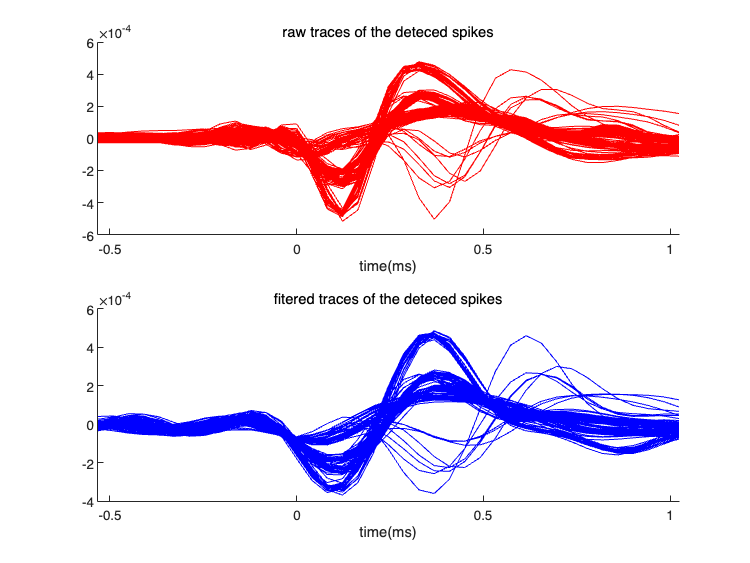

reader = channelReader();
tic 
%                                 filename,        channelColumnIdx, timeColumnIdx, startRowIdx, startColIdx, sampleRate
reader.readMultiChannelFile("./data/1_singleunit wave.xlsx", 1,        3,             7,             4,           nan); %일단 파일을 불러옴

toc % 코드 실행 시간 측정. 오래 걸림.

### (2) read each channel

n_channel = 8
%                                organoid, channel, month 
o1_ch1_m1  = reader.readSingleChannelFromFile(1, 1, 1); %1번 채널 데이터를 불러옴 
o1_ch2_m1  = reader.readSingleChannelFromFile(1, 2, 1); %2번 채널 데이터를 불러옴 
o1_ch3_m1  = reader.readSingleChannelFromFile(1, 3, 1); %3번 채널 데이터를 불러옴 
o1_ch4_m1  = reader.readSingleChannelFromFile(1, 4, 1); %4번 채널 데이터를 불러옴 
o1_ch5_m1  = reader.readSingleChannelFromFile(1, 5, 1); %5번 채널 데이터를 불러옴 
o1_ch6_m1  = reader.readSingleChannelFromFile(1, 6, 1); %6번 채널 데이터를 불러옴 
o1_ch7_m1  = reader.readSingleChannelFromFile(1, 7, 1); %7번 채널 데이터를 불러옴 
o1_ch8_m1  = reader.readSingleChannelFromFile(1, 8, 1); %8번 채널 데이터를 불러옴 
%o1_ch9_m1  = reader.readSingleChannelFromFile(1, 9, 1); %9번 채널 데이터를 불러옴 
%o1_ch10_m1 = reader.readSingleChannelFromFile(1, 10, 1); %10번 채널 데이터를 불러옴 
%o1_ch11_m1 = reader.readSingleChannelFromFile(1, 11, 1); %11번 채널 데이터를 불러옴 
%o1_ch12_m1 = reader.readSingleChannelFromFile(1, 12, 1); %12번 채널 데이터를 불러옴 

### (3) apply filter

o1_ch1_m1.bandPass([300,3000]); %apply bandpass filter 300-3000hz
o1_ch2_m1.bandPass([300,3000]); %apply bandpass filter 300-3000hz
o1_ch3_m1.bandPass([300,3000]); %apply bandpass filter 300-3000hz
o1_ch4_m1.bandPass([300,3000]); %apply bandpass filter 300-3000hz
o1_ch5_m1.bandPass([300,3000]); %apply bandpass filter 300-3000hz
o1_ch6_m1.bandPass([300,3000]); %apply bandpass filter 300-3000hz
o1_ch7_m1.bandPass([300,3000]); %apply bandpass filter 300-3000hz
o1_ch8_m1.bandPass([300,3000]); %apply bandpass filter 300-3000hz
%o1_ch9_m1.bandPass([300,3000]); %apply bandpass filter 300-3000hz
%o1_ch10_m1.bandPass([300,3000]); %apply bandpass filter 300-3000hz
%o1_ch11_m1.bandPass([300,3000]); %apply bandpass filter 300-3000hz
%o1_ch12_m1.bandPass([300,3000]); %apply bandpass filter 300-3000hz

### (4) spike detection

threshold를 5로 하면 channel 에서 spike가 잡히지 않아서 4로 하였습니다.

                       %thres, preTime, postTime
o1_ch1_m1.detectSpikes(4,2,2);
o1_ch2_m1.detectSpikes(4,2,2);

This file has 16 channels: 

ans =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16


o1_ch3_m1.detectSpikes(4,2,2);

경과 시간은 111.528102초입니다.


o1_ch4_m1.detectSpikes(4,2,2);
o1_ch5_m1.detectSpikes(4,2,2);
o1_ch6_m1.detectSpikes(4,2,2);
o1_ch7_m1.detectSpikes(4,2,2);
o1_ch8_m1.detectSpikes(4,2,2);

n_channel = 4

%o1_ch9_m1.detectSpikes(4,2,2);
%o1_ch10_m1.detectSpikes(4,2,2);

channel number = 1
sampling rate = 24414.062743Hz
starts at 0.000000, ends at 23.152517, duration = 23.152517
number of timestamps = 565248



%o1_ch11_m1.detectSpikes(4,2,2);

channel number = 2
sampling rate = 24414.062743Hz
starts at 0.000000, ends at 23.152517, duration = 23.152517
number of timestamps = 565248



%o1_ch12_m1.detectSpikes(4,2,2);

channel number = 3
sampling rate = 24414.062743Hz
starts at 0.000000, ends at 23.152517, duration = 23.152517
number of timestamps = 565248



### (5) pool spikes

this amouts to stacking arrays horizontally.

each row represents a spike.

channel number = 4
sampling rate = 24414.062743Hz
starts at 0.000000, ends at 23.152517, duration = 23.152517
number of timestamps = 565248



spikes_pooled = [o1_ch1_m1.spikeWaveforms; ...

channel number = 5
sampling rate = 24414.062743Hz
starts at 0.000000, ends at 23.152517, duration = 23.152517
number of timestamps = 565248



    o1_ch2_m1.spikeWaveforms; ...

channel number = 6
sampling rate = 24414.062743Hz
starts at 0.000000, ends at 23.152517, duration = 23.152517
number of timestamps = 565248



    o1_ch3_m1.spikeWaveforms; ...

channel number = 7
sampling rate = 24414.062743Hz
starts at 0.000000, ends at 23.152517, duration = 23.152517
number of timestamps = 565248



    o1_ch4_m1.spikeWaveforms; ...

channel number = 8
sampling rate = 24414.062743Hz
starts at 0.000000, ends at 23.152517, duration = 23.152517
number of timestamps = 565248



    o1_ch5_m1.spikeWaveforms; ...
    o1_ch6_m1.spikeWaveforms; ...
    o1_ch7_m1.spikeWaveforms; ...
    o1_ch8_m1.spikeWaveforms; ...
    %o1_ch9_m1.spikeWaveforms; ...
    %o1_ch10_m1.spikeWaveforms; ...
    %o1_ch11_m1.spikeWaveforms; ...
    %o1_ch12_m1.spikeWaveforms
    ];

### (5) record channel membership of spikes

ith element of `membership_channel `represents which channel it belongs to

membership_channel = [repelem(1,o1_ch1_m1.nSpikes), ...
    repelem(2,o1_ch2_m1.nSpikes), ...
    repelem(3,o1_ch3_m1.nSpikes), ...
    repelem(4,o1_ch4_m1.nSpikes), ...
    repelem(5,o1_ch5_m1.nSpikes), ...
    repelem(6,o1_ch6_m1.nSpikes), ...
    repelem(7,o1_ch7_m1.nSpikes), ...
    repelem(8,o1_ch8_m1.nSpikes)...
    ]'; %cluster array와 형식을 맞추기 위해 transpose

### (6) PCA on pooled spikes

standardization(each variable is divided by its standard deviation) is needed when the variables are heterogenous in scales(in our case, each timepoint is a varible)

previous plots used z-scores. 

It's up to researcher's choice whether to standarize the data or not.

cf. https://stats.stackexchange.com/questions/53/pca-on-correlation-or-covariance

waveformZ = zscore(spikes_pooled); %standard scaling. 이 작업을 수행하면 correlation matrix에 대해 PCA를 하는 것이 되고, 수행하지 않으면 covariance matrix에 대해 PCA를 수행하는 것이 됩니다.

number of spikes found : 77


[~,score,~,~,explained] = pca(spikes_pooled); % waveform들에 PCA 적용

number of spikes found : 126


% pick first two PC scores

number of spikes found : 93


PCScores = score(:,1:2);

number of spikes found : 120


PC1 = score(:,1); % first pca score

number of spikes found : 104


PC2 = score(:,2); %second pca score

number of spikes found : 109


#### (7) Run k-means

n_cluster = 3; % 클러스터 개수 설정. k-means는 정해진 클러스터 개수로 데이터를 나누려고 시도하는 알고리즘입니다. 클러스터 개수는 알고리즘이 스스로 정하지 못하며 사용자가 지정해 주어야 합니다.

number of spikes found : 95


rng(1); % 시드 넘버 설정

number of spikes found : 120


[clusters, centroid] = kmeans(PCScores, n_cluster);%주어진 cluster개수로 kmeans 실행 



#### (8) color gradation function

color code: (RGB in [0,1] scale)

you can pick any color you want.

https://www.tug.org/pracjourn/2007-4/walden/color.pdf

%blue
lightBLUE = [0.356862745098039,0.811764705882353,0.956862745098039];
darkBLUE = [0.0196078431372549,0.0745098039215686,0.670588235294118];
 
blueGRADIENTflexible = @(i,N) lightBLUE + (darkBLUE-lightBLUE)*((i-1)/(N-1));

%red
lightRED = [1, 0.5, 0.5];
darkRED = [0.5, 0, 0];
 
redGRADIENTflexible = @(i,N) lightRED + (darkRED-lightRED)*((i-1)/(N-1));

%green
lightGREEN = [0.5, 0.8, 0.5];
darkGREEN = [0.07, 0.38, 0.07];
 
greenGRADIENTflexible = @(i,N) lightGREEN + (darkGREEN-lightGREEN)*((i-1)/(N-1));

#### (9) draw plots

if we change the number of clusters, we need to manually copy,  paste and modify the for loop.

number 6 indicages the marker size

%cluster 1
for i = 1 : n_channel
                     %spikes   belong to ith channel    and 1st cluster
    membership = logical((membership_channel == i) .* (clusters == 1));
    sum(membership)
    color_now = blueGRADIENTflexible(i,n_channel);
                                                    %marker size    
    scatter3(PC1(membership,:), PC2(membership,:) ,i, 6, color_now, "filled")
    hold on;
end
%cluster 2
for i = 1 : n_channel
                %spikes   belong to ith channel    and 2nd cluster
    membership = logical((membership_channel == i) .* (clusters == 2));
    sum(membership)
    color_now = redGRADIENTflexible(i,n_channel);
    scatter3(PC1(membership,:), PC2(membership,:) ,i, 6, color_now, "filled")
    hold on;

end        
%cluster 3
for i = 1 : n_channel
                    %spikes   belong to ith channel    and 3rd cluster
    membership = logical((membership_channel == i) .* (clusters == 3));
    sum(membership)
    color_now = greenGRADIENTflexible(i,n_channel);
    scatter3(PC1(membership,:), PC2(membership,:) ,i, 6, color_now, "filled")
    hold on;
end  
hold off; % put your cursor on the upper right side of the figure; then an arrow appears. click it to see the figure on the separate window.

## Figure 2.h.2 (scatterplot data export)

h = gcf; %가장 최근에 그린 figure를 집어옴
axesObjs = get(h, 'Children') %figure의 하위 object들을 가져옴. 
dataObjs = get(axesObjs(3), 'Children') %scatter plot에 해당하는 axes를 가져옴
dataObjs(1); % cluster 3
dataObjs(2); % cluster 2
dataObjs(3)  % cluster 1
cluster1X = (dataObjs(3).XData)'
cluster1Y = (dataObjs(3).YData)'
writetable(table(cluster1X, cluster1Y), "scatterData.xlsx") %파일명을 .xlsx로 하여 엑셀 파일로 저장

## Figure 2.h. part 2

**mean spike of each cluster**

**cluster별 mean spike 정보 가져오는 method:**

- `channelobject.getClusterMeanSpikes(clusterNum)`

`논문에서는  ylim 통일했음. 이 예제에서는 통일하지 않았음. ylim옵션을 통해 쉽게 통일 가능`

figure

%cluster 1
[meanSpikeWaveform_1, std_1, tRangeCentered, nSpikes] =  o1_ch8_m1.getClusterMeanSpike(1);

subplot(3,1,1)
plot(tRangeCentered, meanSpikeWaveform_1 + 1*std_1, 'k--', 'LineWidth', 1, 'Color', "red"); %mean + 1sd 그리기
hold on;
plot(tRangeCentered, meanSpikeWaveform_1 - 1*std_1, 'k--', 'LineWidth', 1, 'Color', "red"); %mean - 1sd 그리기
hold on;

%curve 사이 색칠하기(오류 발생 가능)
t2 = [tRangeCentered, fliplr(tRangeCentered)];
inBetween = [meanSpikeWaveform_1 - 1*std_1, fliplr(meanSpikeWaveform_1 + 1*std_1)];
fill(t2, inBetween, "red");
hold on;

plot(tRangeCentered, meanSpikeWaveform_1,'Linewidth',2,'Color','k'); %meanSpike 그리기

hold off;
title("mean spike of cluster 1")

ans = 0

ans = 15

ans = 10

ans = 43

ans = 21

ans = 34

ans = 31

ans = 37




%cluster 2
[meanSpikeWaveform_2, std_2, tRangeCentered_2, nSpikes_2] =  o1_ch8_m1.getClusterMeanSpike(2);

subplot(3,1,2)
plot(tRangeCentered_2, meanSpikeWaveform_2 + 1*std_2, 'k--', 'LineWidth', 1, 'Color', "blue"); %mean + 1sd 그리기
hold on;

ans = 77

ans = 70

ans = 75

ans = 55

ans = 64

ans = 52

ans = 51

ans = 60

plot(tRangeCentered_2, meanSpikeWaveform_2 - 1*std_2, 'k--', 'LineWidth', 1, 'Color', "blue"); %mean - 1sd 그리기
hold on;
plot(tRangeCentered_2, meanSpikeWaveform_2,'Linewidth',2,'Color','k'); %meanSpike 그리기
hold off;

title("mean spike of cluster 2")


%cluster 3

ans = 0

ans = 41

ans = 8

ans = 22

ans = 19

ans = 23

ans = 13

ans = 23

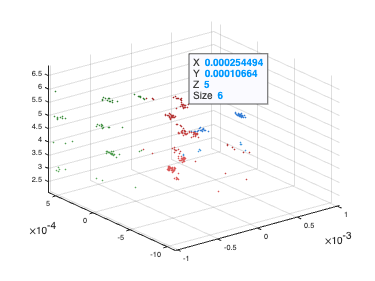

[meanSpikeWaveform_3, std_3, tRangeCentered_3, nSpikes_3] =  o1_ch8_m1.getClusterMeanSpike(3);


subplot(3,1,3)
plot(tRangeCentered_3, meanSpikeWaveform_3 + 1*std_3, 'k--', 'LineWidth', 1, 'Color', "green"); %mean + 1sd 그리기
hold on;
plot(tRangeCentered_3, meanSpikeWaveform_3 - 1*std_3, 'k--', 'LineWidth', 1, 'Color', "green"); %mean - 1sd 그리기

ans =      1     1     1     1     1     1     1     1     1     1


hold on;
plot(tRangeCentered_3, meanSpikeWaveform_3,'Linewidth',2,'Color','k'); %meanSpike 그리기
hold off;
%ylim([-2.5, 2.5]*1e4) %ylim 통일 가능
title("mean spike of cluster 3")

sgtitle("figure 2.h. part 2")

## Figure 2.h.3.1 (many spikes, colored by cluster)

Spike peak 앞뒤로 몇 ms를 그릴지 설정. 아래의 값만 설정하면 시간에 대해서는 수정할 것이 없습니다.

ms_pre_peak = 0.5; % peak 앞쪽
ms_post_peak = 1.0; % peak 뒷쪽
%                 올림                이 데이터에서 timestamp 하나의 milisecond 길이

n_timestamps_pre_peak = ceil(ms_pre_peak / o1_ch8_m1.msPerTs);
%                 올림                이 데이터에서 timestamp 하나의 milisecond 길이
n_timestamps_ms_post_peak = ceil(ms_post_peak / o1_ch8_m1.msPerTs);

각 spike의 peak 발생 시간은 spikeTimestamps에 저장되어 있음

spikeTimestamps = o1_ch8_m1.spikeTimestamps;

그래프의 x축에 표시하기 위해, spike peak 앞뒤로 정해놓은 범위를 milisecond로 표현한 array를 생성

t_values = (-n_timestamps_pre_peak : n_timestamps_ms_post_peak) * o1_ch8_m1.msPerTs;

PCA와 K-means 이후에 각 spike가 몇 번째 클러스터에 속해 있는지는 clusters에 저장되어 있음

clusters = o1_ch8_m1.clusters;
clusterColors = ["red", "blue", "green"]; % cluster별 색깔 리스트
figure % start a new figure

    
subplot(2,1,1) %세로 2칸, 가로 1칸 중 첫 번째 칸에 plot 그림 
% raw trace
hold on; % 겹쳐 그리기 시작

for i = 1:o1_ch8_m1.nSpikes
    ts_spike_peak = spikeTimestamps(i); % i번째 spike의 위치 가져오기
    cluster_num = clusters(i); % i번째 spike의 cluster 번호 가져오기
    spike_color = clusterColors(cluster_num);% 해당하는 cluster의 color로 플롯 색깔을 지정
    tsInterval = ts_spike_peak + (-n_timestamps_pre_peak : n_timestamps_ms_post_peak); % spike를 중심으로 waveform의 t축 범위를 timestamp 단위로 정함. 해당 범위에 해당하는 timestamp index를 저장
    pRaw = plot(t_values, o1_ch8_m1.raw(tsInterval)); % raw trace signal에서 앞서 저장한 timestamp index에 해당하는 값을 추출. 즉, spike 파형을 추출

    pRaw.Color = spike_color;%색깔 조절 가능

end
hold off; %겹쳐 그리기 끝
title('raw traces of the deteced spikes, colored by cluster membership');
xlabel('time(s)');
xlim("tight") %automatically sets the x axis limit of the plot
subplot(2,1,2) %세로 2칸, 가로 1칸 중 두 번째 칸에 plot 그림 
% filtered trace
hold on; % 겹쳐 그리기 시작
for i = 1:o1_ch8_m1.nSpikes
    ts_spike_peak = spikeTimestamps(i); % i번째 spike의 위치 가져오기
    cluster_num = clusters(i); % i번째 spike의 cluster 번호 가져오기
    spike_color = clusterColors(cluster_num);% 해당하는 cluster의 color로 플롯 색깔을 지정
    tsInterval = ts_spike_peak + (-n_timestamps_pre_peak : n_timestamps_ms_post_peak); % spike를 중심으로 waveform의 t축 범위를 timestamp 단위로 정함. 해당 범위에 해당하는 timestamp index를 저장
    pfiltered = plot(t_values, o1_ch8_m1.filtered(tsInterval)); % raw trace signal에서 앞서 저장한 timestamp index에 해당하는 값을 추출. 즉, spike 파형을 추출
    pfiltered.Color = spike_color;%색깔 조절 가능

end
hold off; %겹쳐 그리기 끝
title('fitered traces of the deteced spikes, colored by cluster membership');
xlabel('time(s)');
xlim("tight")%automatically sets the x axis limit of the plot

## Figure 2.h.3.2 (many spikes, plot per cluster)

Spike peak 앞뒤로 몇 ms를 그릴지 설정. 아래의 값만 설정하면 시간에 대해서는 수정할 것이 없습니다.

ms_pre_peak = 0.5; % peak 앞쪽
ms_post_peak = 1.0; % peak 뒷쪽
%                 올림                이 데이터에서 timestamp 하나의 milisecond 길이

n_timestamps_pre_peak = ceil(ms_pre_peak / o1_ch8_m1.msPerTs);
%                 올림                이 데이터에서 timestamp 하나의 milisecond 길이
n_timestamps_ms_post_peak = ceil(ms_post_peak / o1_ch8_m1.msPerTs);

각 spike의 peak 발생 시간은 spikeTimestamps에 저장되어 있음

spikeTimestamps = o1_ch8_m1.spikeTimestamps;

그래프의 x축에 표시하기 위해, spike peak 앞뒤로 정해놓은 범위를 milisecond로 표현한 array를 생성

t_values = (-n_timestamps_pre_peak : n_timestamps_ms_post_peak) * o1_ch8_m1.msPerTs;

PCA와 K-means 이후에 각 spike가 몇 번째 클러스터에 속해 있는지는 clusters에 저장되어 있음

clusters = o1_ch8_m1.clusters;
clusterColors = ["red", "blue", "green"]; % cluster별 색깔 리스트

앞의 코드와 거의 같고, cluster 번호에 대한 반복문와 if문을 추가하여 현재 cluster에 해당하는 spike만 모아 subplot을 그리게 함


% raw trace
figure % start a new figure
for c = 1:o1_ch8_m1.nClusters % 각 클러스터 번호마다
    subplot(o1_ch8_m1.nClusters,1,c) %세로 3칸, 가로 1칸 중 c 번째 칸에 plot 그림 
    hold on; % 겹쳐 그리기 시작
    for i = 1:o1_ch8_m1.nSpikes
        ts_spike_peak = spikeTimestamps(i); % i번째 spike의 위치 가져오기
        cluster_num = clusters(i); % i번째 spike의 cluster 번호 가져오기
        if c == cluster_num %현재 클러스터 번호에 대항하는 spike만 그림
            spike_color = clusterColors(cluster_num);% 해당하는 cluster의 color로 플롯 색깔을 지정
            tsInterval = ts_spike_peak + (-n_timestamps_pre_peak : n_timestamps_ms_post_peak); % spike를 중심으로 waveform의 t축 범위를 timestamp 단위로 정함. 해당 범위에 해당하는 timestamp index를 저장
            pRaw = plot(t_values, o1_ch8_m1.raw(tsInterval)); % raw trace signal에서 앞서 저장한 timestamp index에 해당하는 값을 추출. 즉, spike 파형을 추출
            pRaw.Color = spike_color;%색깔 조절 가능
        end %end of if
    end % end of spike loop
    hold off; %겹쳐 그리기 끝  
    title("raw traces of the deteced spikes, cluster " + c);
    xlabel('time(ms)');
    xlim("tight") %automatically sets the x axis limit of the plot
end % end of cluster loop
% filtered trace
figure % start a new figure
for c = 1:o1_ch8_m1.nClusters % 각 클러스터 번호마다
    subplot(o1_ch8_m1.nClusters,1,c) %세로 3칸, 가로 1칸 중 c 번째 칸에 plot 그림 
    hold on; % 겹쳐 그리기 시작
    for i = 1:o1_ch8_m1.nSpikes
        ts_spike_peak = spikeTimestamps(i); % i번째 spike의 위치 가져오기
        cluster_num = clusters(i); % i번째 spike의 cluster 번호 가져오기
        if c == cluster_num %현재 클러스터 번호에 대항하는 spike만 그림
            spike_color = clusterColors(cluster_num);% 해당하는 cluster의 color로 플롯 색깔을 지정
            tsInterval = ts_spike_peak + (-n_timestamps_pre_peak : n_timestamps_ms_post_peak); % spike를 중심으로 waveform의 t축 범위를 timestamp 단위로 정함. 해당 범위에 해당하는 timestamp index를 저장
            pfiltered = plot(t_values, o1_ch8_m1.filtered(tsInterval)); % raw trace signal에서 앞서 저장한 timestamp index에 해당하는 값을 추출. 즉, spike 파형을 추출
            pfiltered.Color = spike_color;%색깔 조절 가능
        end %end of if
    end % end of spike loop
    hold off; %겹쳐 그리기 끝  
    title("filtered traces of the deteced spikes, cluster " + c);
    xlabel('time(ms)');
    xlim("tight") %automatically sets the x axis limit of the plot
end % end of cluster loop

## Figure 2.i

colored raster plot. 

**plot 그리는 method:**

- `channelobject.drawColoredRaster(colorNamesArray):` 클러스터별로 색이 다르게 입혀진 raster plot. spike의 위치를 표시.

figure
o1_ch8_m1.drawColoredRaster(["red", "blue", "green"]);
xlim([0,30]) %xlim, ylim 조절 가능

## Figure 2.j.

interspike intervals histogram

**ISI 데이터(milisecond 단위) 가져오는 method:**

- `channelobject.getISIvalues(clusterNum)`

**히스토그램 그리는 matlab 기본 함수 : **`histogram`

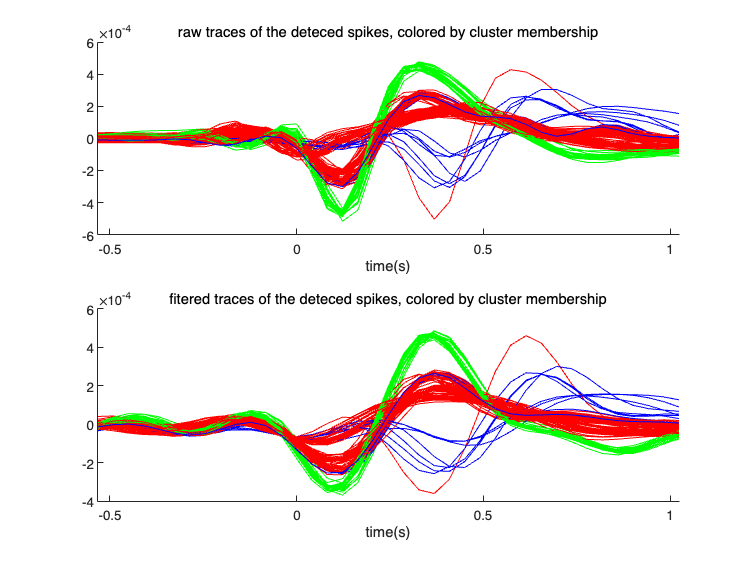

figure
subplot(1,3,1)
[ISIvalues_1, nSpikes] = o1_ch8_m1.getISIvalues(1); %cluster 1의 ISI 계산값 가져오기
h1 = histogram(ISIvalues_1, 20); % bin 개수 20개로 설정. 변경 가능
title('cluster ' + string(1) + ', n = ' + string(nSpikes) ); %subplot 제목 
xlabel('ISI (ms)'); % subplot x축 변수 이름
h1.FaceColor = "red"; %색상 지정

subplot(1,3,2)
[ISIvalues_2, nSpikes_2] = o1_ch8_m1.getISIvalues(2); %cluster 2의 ISI 계산값 가져오기
h2 = histogram(ISIvalues_2, 20); % bin 개수 20개로 설정. 변경 가능
title('cluster ' + string(2) + ', n = ' + string(nSpikes_2) ); %subplot 제목 
xlabel('ISI (ms)'); % subplot x축 변수 이름 
h2.FaceColor = "blue"; %색상 지정

subplot(1,3,3)
[ISIvalues_3, nSpikes_3] = o1_ch8_m1.getISIvalues(3); %cluster 3의 ISI 계산값 가져오기
h3 = histogram(ISIvalues_3, 20); % bin 개수 20개로 설정. 변경 가능
title('cluster ' + string(3) + ', n = ' + string(nSpikes_3) ); %subplot 제목 
xlabel('ISI (ms)'); % subplot x축 변수 이름 

h3.FaceColor = "green"; %색상 지정

## Figure 2.k

theta waves and theta phase

thetaPhase의 경우, y축 범위가 (-pi, pi)임. 논문에서는 y축 스케일을 조절해 trace 모양이 잘 드러나게 하였음. 여기서는 원본 스케일을 써서 논문과 다르게 보임. matlab의 plot함수의 옵션을 사용하여 조절 가능.

**channel object에서 데이터 접근 방법**

- `channelobject.thetaWaves`: theta wave trace array

- `channelobject.thetaPhases`: theta angle array

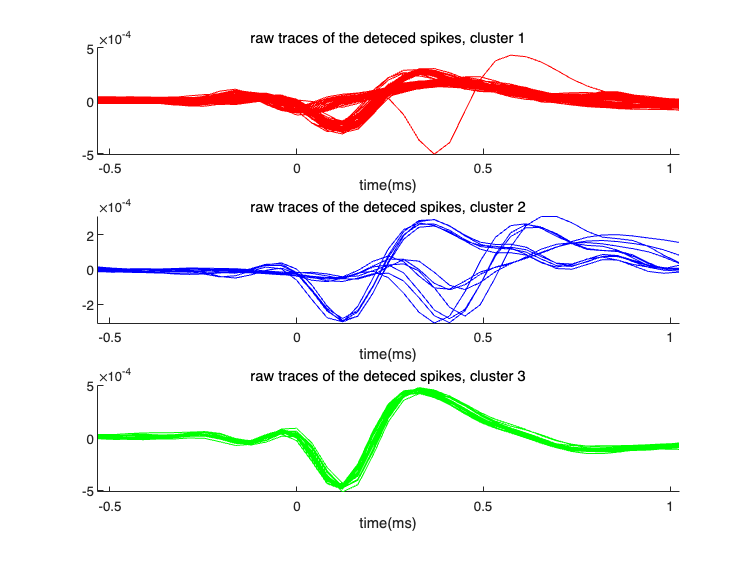

figure
subplot(3,1,1)
p_raw = plot(o1_ch8_m1.t, o1_ch8_m1.raw); %raw trace plot
p_raw.Color = 'red'; %색깔 조절

hold on;

p_thetaWaves = plot(o1_ch8_m1.t, o1_ch8_m1.thetaWaves); %theta wave plot
p_thetaWaves.Color = 'blue'; %색깔 조절
legend("raw trace", "theta trace")
title("raw trace and theta trace")
hold off;


subplot(3,1,2)
p_thetaPhases = plot(o1_ch8_m1.t, o1_ch8_m1.thetaPhases);
p_thetaPhases.Color = 'blue'; %색깔 조절
title("theta phase unscaled")

subplot(3,1,3)
p_thetaPhases = plot(o1_ch8_m1.t, o1_ch8_m1.thetaPhases);
p_thetaPhases.Color = 'blue'; %색깔 조절
ylim([-30, 30])
title("theta phase with scaled y axis")

## Figure 2.m

Circular distrubution of theta phases(angles) at spikes

figure 2.j와 비슷한 방식으로 사용

**phase 데이터 가져오는 method 이름**

- `channelobject.getThetaPhaseByClusterNum(clusterNum)`

**circular histogram 그리는 matlab 함수(circstat 애드온): **`circ_plot`

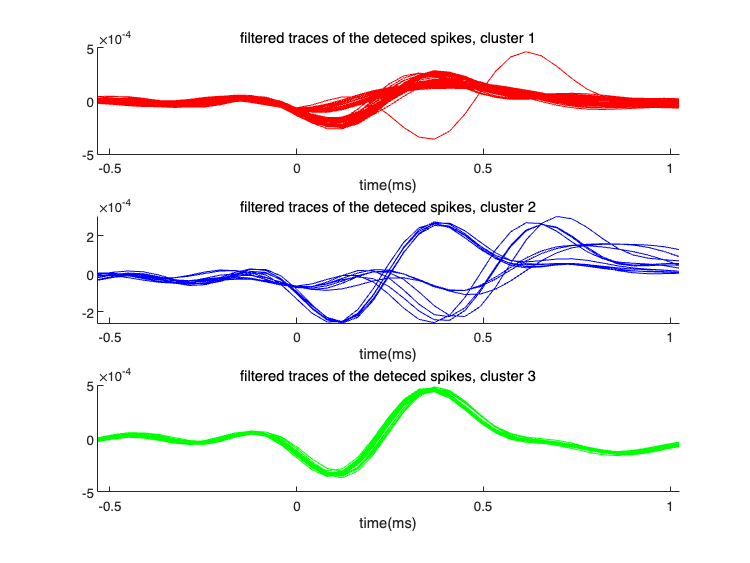

figure
subplot(1,3,1)
[phaseValues_1, nSpikes] = o1_ch8_m1.getThetaPhaseByClusterNum(1); %cluster 1의 phase 계산값 가져오기
circ_plot(phaseValues_1,'hist',[],20,true,false); %bin 개수 20개로 설정. 변경 가능
title('cluster ' + string(1) + ', n = ' + string(nSpikes) ); %subplot 제목 

subplot(1,3,2)
[phaseValues_2, nSpikes_2] = o1_ch8_m1.getThetaPhaseByClusterNum(2); %cluster 2의 phase 계산값 가져오기
circ_plot(phaseValues_2,'hist',[],20,true,false); %bin 개수 20개로 설정. 변경 가능
title('cluster ' + string(2) + ', n = ' + string(nSpikes_2) ); %subplot 제목 

subplot(1,3,3)
[phaseValues_3, nSpikes_3] = o1_ch8_m1.getThetaPhaseByClusterNum(3); %cluster 1의 phase 계산값 가져오기
circ_plot(phaseValues_3,'hist',[],20,true,false); %bin 개수 20개로 설정. 변경 가능
title('cluster ' + string(3) + ', n = ' + string(nSpikes_3) ); %subplot 제목 

sgtitle("figure 2.m. circular distrubution of theta phases(angles) at spikes") %전체 제목

## Figure 2.n. 

distrubution of theta phases(angles) at spikes

figure 2.m에서 사용한 데이터를 `histgoram` 함수에 적용하면 됨

figure
subplot(1,3,1)
[phaseValues_1, nSpikes] = o1_ch8_m1.getThetaPhaseByClusterNum(1); %cluster 1의 phase 계산값 가져오기
h1 = histogram(phaseValues_1, 20); % bin 개수 20개로 설정. 변경 가능
title('cluster ' + string(1) + ', n = ' + string(nSpikes) ); %subplot 제목 
h1.FaceColor = "red"; %색상 지정

subplot(1,3,2)
[phaseValues_2, nSpikes_2] = o1_ch8_m1.getThetaPhaseByClusterNum(2); %cluster 2의 phase 계산값 가져오기
h2 = histogram(phaseValues_2, 20); % bin 개수 20개로 설정. 변경 가능
title('cluster ' + string(2) + ', n = ' + string(nSpikes_2) ); %subplot 제목 
h2.FaceColor = "blue"; %색상 지정

subplot(1,3,3)
[phaseValues_3, nSpikes_3] = o1_ch8_m1.getThetaPhaseByClusterNum(3); %cluster 1의 phase 계산값 가져오기
h3 = histogram(phaseValues_3, 20); % bin 개수 20개로 설정. 변경 가능
title('cluster ' + string(3) + ', n = ' + string(nSpikes_3) ); %subplot 제목 
h3.FaceColor = "green"; %색상 지정

sgtitle("figure 2.n. distrubution of theta phases(angles) at spikes") %전체 제목

## Uniform test(phase-locking detection)

testing the non-uniformty of theta phase distribution using Rayleigh criterion to detect phase-locking.

We considered that phase-locking to theta waves happens for P-values below 0.05.

- phase-locking: theta wave의 특정 phase에서 spike가 유독 많이 일어나는 현상. Phase-locking이 없다면, spike에서의 theta angle분포는 uniform 분포를 따를 것. 따라서 theta angle 분포가 uniform distribution과 같은지 가설검정을 수행. 논문에서는 p-value 기준 0.05를 사용. 0.05보다 작으면 phase-locking. 0.05보다 크면 phase-locking 없는 것으로 판단.

**test 수행하는 함수 이름**

- **channelobject.uniformTest()**: cluster 순서대로 p-value 를 출력.

o1_ch8_m1.uniformTest()

# figure 2 후반부: longtermAnalyzer 클래스 소개 및 plot 재현

월별 비교를 위해 여러 channel의 데이터를 모아서 관리하는 class

일단 여러개의 data file을 불러오고, data 처리를 진행

%불러오기 

%organoid, ch, month
o1_ch1_m1 = reader.readSingleChannelFromFile(1, 1, 1);
o1_ch2_m1 = reader.readSingleChannelFromFile(1, 2, 1);
o2_ch1_m1 = reader.readSingleChannelFromFile(2, 1, 1); 
o2_ch2_m2 = reader.readSingleChannelFromFile(2, 2, 2); 
o3_ch1_m2 = reader.readSingleChannelFromFile(3, 1, 2); 
o2_ch1_m2 = reader.readSingleChannelFromFile(2, 2, 2); 

%bandpass filter
o1_ch1_m1.bandPass([300,3000]);
o1_ch2_m1.bandPass([300,3000]);
o2_ch1_m1.bandPass([300,3000]);
o2_ch2_m2.bandPass([300,3000]);
o3_ch1_m2.bandPass([300,3000]);
o2_ch1_m2.bandPass([300,3000]);

%spike detection
o1_ch1_m1.detectSpikes(3,2,2);
o1_ch2_m1.detectSpikes(3,2,2);
o2_ch1_m1.detectSpikes(3,2,2);
o2_ch2_m2.detectSpikes(3,2,2);
o3_ch1_m2.detectSpikes(3,2,2);
o2_ch1_m2.detectSpikes(3,2,2);
%theta calculation
o1_ch1_m1.getThetas();
o1_ch2_m1.getThetas();
o2_ch1_m1.getThetas();
o2_ch2_m2.getThetas();
o3_ch1_m2.getThetas();
o2_ch1_m2.getThetas();

**longtermAnalyzer object 생성**

- **LAobject.addChannel(channelobject)**: 데이터 처리 완료한 channel object를 longtermAnalyzer object에 추가

la = longtermAnalyzer(); %longtermAnalyzer object 생성

%channel object 추가
la.addChannel(o1_ch1_m1);
la.addChannel(o1_ch2_m1);
la.addChannel(o2_ch1_m1);
la.addChannel(o2_ch2_m2);
la.addChannel(o3_ch1_m2);
la.addChannel(o2_ch1_m2);

## Figure 2.o

월별 히스토그램. 

channel을 지정하면 월별로 모든 organoid를 aggregate.

내부에서 FWHm 계산하는 함수:

- `LAobject.FWHm(spikeWaveform, msPerTs)`**: **spikewaveform 하나에서 minimum 값의 절반을 계산한 뒤, 그 값보다 작은 값이 나온 첫 번째 timestamp와 마지막 timestamp를 찾아서 그 너비를 milisecond로 환산. Spike가 unimodal이 아닐 경우 FWHm값이 크게 나올 수 있음.

- `LAobject.getFWHmsForChannel: `channel 하나에 있는 모든  spike waveform에 대해  FWHm을 계산

figure

[FWHmPoints_1, organoidLabels_1, meanFWHm_1] = la.getFWHmHistByMonth(1, 1); %month 1, channel 1
[FWHmPoints_2, organoidLabels_2, meanFWHm_2] = la.getFWHmHistByMonth(2, 1); %month 2, channel 1
%month 1에는 channel 1이 두 개, month 2에는 channel 1이 한 개 있기 때문에 FWHm 값 개수도
%channel 1이 channel 2의 두 배임.

%barplot
bar([meanFWHm_1, meanFWHm_2]); 


%+- std
hold on

%%month 1 std line
monthNow = 1;
sdFWHm = std(FWHmPoints_1);
upperLimit = meanFWHm_1 + sdFWHm;
lowerLimit = meanFWHm_1 - sdFWHm;
plot([monthNow, monthNow], [lowerLimit,upperLimit], 'k','LineWidth',2);  % 세로선
plot([monthNow-0.1, monthNow+0.1], [lowerLimit,lowerLimit], 'k','LineWidth',2); %아래쪽 가로선
plot([monthNow-0.1, monthNow+0.1], [upperLimit,upperLimit], 'k','LineWidth',2);  %위쪽 가로선

%%month 2 std line
monthNow = 2;
sdFWHm = std(FWHmPoints_2);
upperLimit = meanFWHm_2 + sdFWHm;
lowerLimit = meanFWHm_2 - sdFWHm;
plot([monthNow, monthNow], [lowerLimit,upperLimit], 'k','LineWidth',2);  % 세로선
plot([monthNow-0.1, monthNow+0.1], [lowerLimit,lowerLimit], 'k','LineWidth',2); %아래쪽 가로선
plot([monthNow-0.1, monthNow+0.1], [upperLimit,upperLimit], 'k','LineWidth',2);  %위쪽 가로선


%plot points colored by organoids
%% month 1

monthNow = 1;
x = repelem(monthNow, length(FWHmPoints_1));
y = FWHmPoints_1;
colors = organoidLabels_1;
scatter(x, y, [], colors, 'filled');
            
%% month 2
monthNow = 2;
x = repelem(monthNow, length(FWHmPoints_2));
y = FWHmPoints_2;
colors = organoidLabels_2;
scatter(x, y, [], colors, 'filled');

hold off

xlabel("month")
ylabel("FWHm(ms)")
sgtitle("figure 2.o")

## Figure 2.p.

phase-space analysis

figure 4.f와 동일

## Figure 2.q.

월별 cluster 개수 비교

월별 mean spike by clusters

월별 colored raster plot

앞의 plot 방법들을 조합하여 해결 가능

## Figure 4.b.

여러 데이터 불러오기

                             %organoid, channel, month     
o1_ch1_m1 = reader.readSingleChannelFromFile(1, 1, 1);
o1_ch2_m1 = reader.readSingleChannelFromFile(1, 2, 1);
o1_ch1_m2 = reader.readSingleChannelFromFile(1, 3, 2); %month별로 그림이 달라지게 하기 위해 channel 3을 로드
o1_ch2_m2 = reader.readSingleChannelFromFile(1, 4, 2); %month별로 그림이 달라지게 하기 위해 channel 4를 로드

100-3000hz로 필터링

o1_ch1_m1.bandPass([100,3000])
o1_ch2_m1.bandPass([100,3000])
o1_ch1_m2.bandPass([100,3000])
o1_ch2_m2.bandPass([100,3000])

cluster 개수 3개, spike waveform 길이 +- 2ms로 spike detection 실행

o1_ch1_m1.detectSpikes(3,2,2)
o1_ch2_m1.detectSpikes(3,2,2)
o1_ch1_m2.detectSpikes(3,2,2)
o1_ch2_m2.detectSpikes(3,2,2)

channel object별로 raw trace 그리기. ylim 옵션을 이용해 비교대상끼리 y축 스케일 통일.

figure
%month 1

%ch1
subplot(2,2,1)
p = plot(o1_ch1_m1.t, o1_ch1_m1.raw);
p.Color = 'red';
title('ch1, month 1');
ylim([-1,1]*1e-3);%ylim 조절

%ch2
subplot(2,2,3)
p_o1_ch2_m1 = plot(o1_ch2_m1.t, o1_ch2_m1.raw);
p_o1_ch2_m1.Color = 'blue';
title('ch2, month 1');
ylim([-1,1]*1e-3);%ylim 조절


%month 2
%ch1
subplot(2,2,2)
p_o1_ch1_m2 = plot(o1_ch1_m2.t, o1_ch1_m2.raw);
p_o1_ch1_m2.Color = 'red';
title('ch1, month 2');
ylim([-1,1]*1e-3);%ylim 조절

%ch2
subplot(2,2,4)
p_o1_ch2_m2 = plot(o1_ch2_m2.t, o1_ch2_m2.raw);
p_o1_ch2_m2.Color = 'blue';
title('ch2, month 2')
ylim([-1,1]*1e-3);%ylim 조절
% 
sgtitle("figure 4.b. part1.")



channel object별로 mean spike 그리기.

**channel object의 전체 mean spike 정보 가져오는 method:**

- `channelobject.getTotalMeanSpike()`

figure

[meanSpikeWaveform_1, std_1, tRangeCentered_1, nSpikes_1] =  o1_ch1_m1.getTotalMeanSpike();
[meanSpikeWaveform_2, std_2, tRangeCentered_2, nSpikes_2] =  o1_ch2_m1.getTotalMeanSpike();
[meanSpikeWaveform_3, std_3, tRangeCentered_3, nSpikes_3] =  o1_ch1_m2.getTotalMeanSpike();
[meanSpikeWaveform_4, std_4, tRangeCentered_4, nSpikes_4] =  o1_ch2_m2.getTotalMeanSpike();


subplot(4,1,1)
plot(tRangeCentered_1, meanSpikeWaveform_1 + 1*std_1, 'k--', 'LineWidth', 1, 'Color', "red"); %mean + 1sd 그리기
hold on;
plot(tRangeCentered_1, meanSpikeWaveform_1 - 1*std_1, 'k--', 'LineWidth', 1, 'Color', "red"); %mean - 1sd 그리기
hold on;

%curve 사이 색칠하기(오류 발생 가능)
t2 = [tRangeCentered_1, fliplr(tRangeCentered_1)];
inBetween = [meanSpikeWaveform_1 - 1*std_1, fliplr(meanSpikeWaveform_1 + 1*std_1)];
fill(t2, inBetween, "red");
hold on;

plot(tRangeCentered_1, meanSpikeWaveform_1,'Linewidth',2,'Color','k'); %meanSpike 그리기

hold off;

title('mean spike of ch1, month1');

subplot(4,1,2)
plot(tRangeCentered_2, meanSpikeWaveform_2 + 1*std_2, 'k--', 'LineWidth', 1, 'Color', "blue"); %mean + 1sd 그리기
hold on;
plot(tRangeCentered_2, meanSpikeWaveform_2 - 1*std_2, 'k--', 'LineWidth', 1, 'Color', "blue"); %mean - 1sd 그리기
hold on;
plot(tRangeCentered_2, meanSpikeWaveform_2,'Linewidth',2,'Color','k'); %meanSpike 그리기
hold off;
title('mean spike of ch2, month1');

subplot(4,1,3)
plot(tRangeCentered_3, meanSpikeWaveform_3 + 1*std_3, 'k--', 'LineWidth', 1, 'Color', "green"); %mean + 1sd 그리기
hold on;
plot(tRangeCentered_3, meanSpikeWaveform_3 - 1*std_3, 'k--', 'LineWidth', 1, 'Color', "green"); %mean - 1sd 그리기
hold on;
plot(tRangeCentered_3, meanSpikeWaveform_3,'Linewidth',2,'Color','k'); %meanSpike 그리기
hold off;
title('mean spike of ch1, month2');

subplot(4,1,4)
plot(tRangeCentered_4, meanSpikeWaveform_4 + 1*std_4, 'k--', 'LineWidth', 1, 'Color', "magenta"); %mean + 1sd 그리기
hold on;
plot(tRangeCentered_4, meanSpikeWaveform_4 - 1*std_4, 'k--', 'LineWidth', 1, 'Color', "magenta"); %mean - 1sd 그리기
hold on;
plot(tRangeCentered_4, meanSpikeWaveform_4,'Linewidth',2,'Color','k'); %meanSpike 그리기
hold off;

title('mean spike of ch2, month2');

sgtitle("figure 4.b. part 2")

## Figure 4.c.

spectrogram

x축 0s = 데이터 시작 시간(이 데이터에서는 약 30s)

matlab signal processing toolbox의 spectrogram 함수 사용

figure
subplot(2,1,1)
spectrogram(o1_ch1_m2.raw, [], [], [], o1_ch1_m2.sf, 'yaxis')
title('ch1, month2, raw signal')%raw

subplot(2,1,2)
spectrogram(o1_ch1_m2.filtered, [], [], [], o1_ch1_m2.sf, 'yaxis')
title('ch1, month2, filtered signal')

## Figure 4.d

power spectrums

timetable 함수와 signal processing toolbox의 pspectrum 함수 사용

 transpose가 필요함에 유의

figure

xTable = timetable(seconds((o1_ch1_m1.t)'), (o1_ch1_m1.raw)'); 
[pxx,f] = pspectrum(xTable);
month1 = plot(f,pow2db(pxx));
month1.Color = 'red';

hold on

xTable = timetable(seconds((o1_ch1_m2.t)'), (o1_ch1_m2.raw)'); 
[pxx,f] = pspectrum(xTable);
month2 = plot(f,pow2db(pxx));
month2.Color = 'blue';

grid on

legend('month1', 'month2');
xlabel('Frequency (Hz)');
ylabel('Power Spectrum (dB)');
title('Default Frequency Resolution');

## Figure 4.f.

**phase-space analysis**

- 월별로 mean spike를 비교하였으나, 어떤 waveform이라도 대입하면 그릴 수 있음

- "normalize" : v, dv/dt를 각각의 minimum으로 나눔

figure


%month 1
averageWaveform = mean(o1_ch1_m1.spikeWaveforms);
dVdt = diff(averageWaveform)/o1_ch1_m1.msPerTs;

%%normalize
averageWaveform = averageWaveform / min(averageWaveform);     
dVdt = dVdt / min(dVdt);

%%algorithm for drawing pahse space plot
color = "red";
V = averageWaveform(1:(end-1));
hold on
for i = 1: (length(dVdt)-1)
    p = plot([V(i), V(i+1)], [dVdt(i), dVdt(i+1)], 'k');
    p.Color = color;
end






%month 2
averageWaveform = mean(o1_ch1_m2.spikeWaveforms);
dVdt = diff(averageWaveform)/o1_ch1_m2.msPerTs;

%normalize
averageWaveform = averageWaveform / min(averageWaveform);     
dVdt = dVdt / min(dVdt);

%algorithm for drawing pahse space plot
color = "blue";
V = averageWaveform(1:(end-1));
hold on
for i = 1: (length(dVdt)-1)
    p = plot([V(i), V(i+1)], [dVdt(i), dVdt(i+1)], 'k');
    p.Color = color;
end
hold off
legend('month1', 'month2')

- figure 4.g.는 figure 2.o와 동일

- figure 4.e, h는 figure 2.o에서 FWHm만 signal power와 spikes count per neuron으로 바꾸면 됨

- figure 4.i 아직 이해 못함

- figure 5는 figure 2의 방법으로 모두 구현 가능

o1_ch1_m1